filelist = ["data_08-Apr-2025_16-28-51.mat" %1->30 rads
   "data_08-Apr-2025_16-31-40.mat"       %30->40 rads
]

filelist = 2×1 string array
    "data_08-Apr-2025_16-28-51.mat"
    "data_08-Apr-2025_16-31-40.mat"


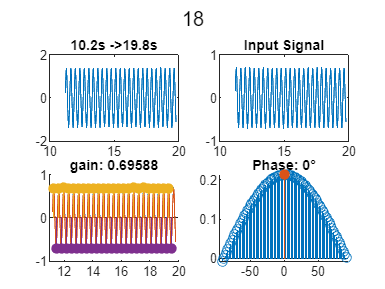

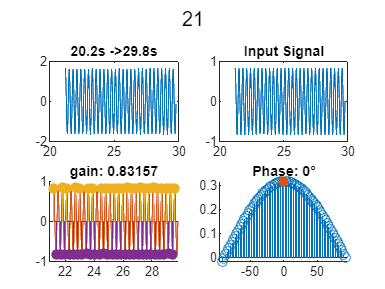

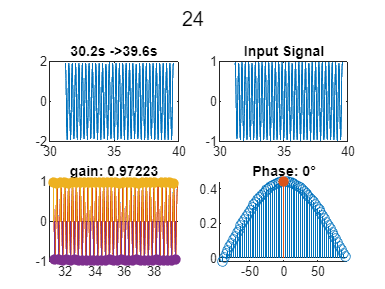

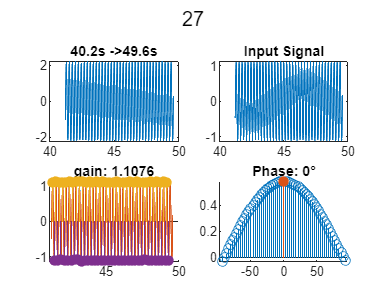

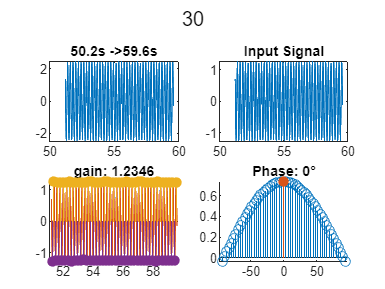

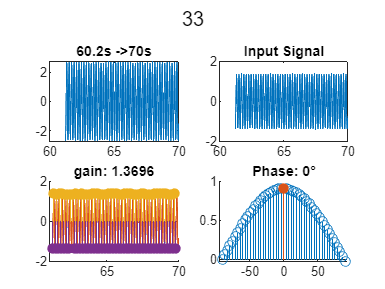

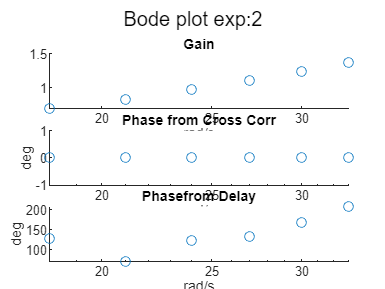



omega_stairs = load("lab5\stairs (1).mat");
om1 = omega_stairs.x1to30with10s_pause{1};
om2 =  omega_stairs.x30to40with10s_pause{1};
om3 = omega_stairs.x15to35sparse10{1}.Values;
omTSf = {om3; om3};
tstart_d=1;
tend_d=0;
do_plots = true;
bias_angle = deg2rad(7);
amp = 2;
tableofData = [];
for exp_id = 2:2
    filename = "lab5/data/"+filelist(exp_id);
    data = load(filename).data;
    time = data(1,:);
    S_out = (data(5,:))/amp; % u is output
    S_in = ((data(11,:))-bias_angle); % ref is normalized input

    omeTs=resample(omTSf{exp_id},time);
    om = omeTs.Data;
    slices = sliceTimeSeries(time,om);
    
    for i = 1:size(slices,2)
        if (exp_id ==2 && (i==1 ||i==12) ) || (exp_id ==1 && (i==29 ||i==30))

        slices{i}.phase = NaN;
        slices{i}.gain = NaN;
        slices{i}.phase_del = NaN;
            continue
        end
        omega = slices{i}.f;
        focus = slices{i};
    
        t_start_idx = time2index(focus.t_start+tstart_d);
        t_end_idx = time2index(focus.t_end-tend_d);
       
    
        t_focus= time(t_start_idx:t_end_idx);
        om_focus= om(t_start_idx:t_end_idx);
        i_focus= S_inp(t_start_idx:t_end_idx);
        o_focus= S_out(t_start_idx:t_end_idx);
        if do_plots
            figure
            subplot(2,2,1)
                plot(t_focus,i_focus)
                title(focus.t_start + "s ->" + focus.t_end + "s")
            subplot(2,2,2)
                plot(t_focus,o_focus)
                title("Input Signal")
            subplot(2,2,[3 4])
        end
        [phase, gain, phase_del] = SweepAnalysis(t_focus,i_focus, o_focus, omega, do_plots);
        slices{i}.phase = phase;
        slices{i}.gain = gain;
        slices{i}.phase_del = phase_del;
    end
    
    [freqs,phases, gains, phase_dels] = flatten(slices);
        if do_plots
        figure
        sgtitle("Bode plot exp:" + exp_id)
        subplot(3,1,1)
        scatter(freqs,gains)
        xscale("log")
        title("Gain")
        xlabel("rad/s")
        % ylim([0.9, 1.1])

        
        subplot(3,1,2)
        scatter(freqs,rad2deg(phases))
        xscale("log")
        % ylim([0 90])
        title("Phase from Cross Corr")
        xlabel("rad/s")
        ylabel("deg")
        
        
        subplot(3,1,3)
        scatter(freqs,rad2deg(phase_dels))
        xscale("log")
        % ylim([0 90])
        title("Phasefrom Delay")
        xlabel("rad/s")
        ylabel("deg")
    end
    %
    % Save file
    tableofData = [tableofData; [freqs; phases; gains]' ];



end



writematrix(tableofData, "lab5/effort0", FileType="spreadsheet",WriteMode="overwritesheet")



%get model params
mu = -1.4684;
tau =  0.0409;
kp = -21.4;
kd = -0.43;

G = tf([mu],[tau 1 0]);
C = pid(kp,0,kd);
L=G*C;
T = feedback(C,L,-1);
% T_d = c2d(T,1/500);
[g_T,p_T,ome_T] = bode(T,{1,40});
ang_T = 1*(reshape(p_T(1,1,:),1,[]));
g_T_f = reshape(g_T(1,1,:),1,[]);




% [tid_g,tid_p,tid_w]=bode(tf1,{1,40});
% ang_Tid = 1*(reshape(tid_p(1,1,:),1,[]));
% g_Tid_f = reshape(tid_g(1,1,:),1,[]);


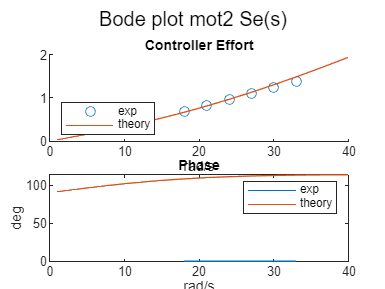

%merge
% PHASE
omegas = tableofData(:,1);
phases = tableofData(:,2);
gains = tableofData(:,3);

figure
sgtitle("Bode plot mot2 Se(s)")
subplot(2,1,1)
scatter(omegas,gains)
hold on
plot(ome_T,g_T_f)
% plot(tid_w,g_Tid_f)
% yscale("log")
title("Controller Effort")
xlabel("rad/s")
% ylim([0 1.1])
% ylim([0 1.1])
legend(["exp", "theory"], "Location", 'southwest')
hold  off

subplot(2,1,2)
plot(omegas,rad2deg(phases))
hold on
plot(ome_T,ang_T)
title("Phase")
xlabel("rad/s")
ylabel("deg")
hold  off
legend(["exp","theory"])


function idx = time2index(time)
idx = floor(time/0.002)+1;
end

function [freqs, phases, gain, phase_dels] = flatten(slices)
    freqs = [];
    phases = [];
    gain = [];
    phase_dels = [];
    for i = 1:size(slices,2)
    freqs(i) = slices{i}.f;
    phases(i) = slices{i}.phase;
    gain(i) = slices{i}.gain;
    phase_dels(i) = slices{i}.phase_del;
    end

end